For the document network data, the input is two matrices including the m x n document content matrix W and the m x m citation link matrix C

clear classes

clear all
close all
clc

rng(213);        % code initialized
load('../Data/citeseer.mat');    % the sythetic temporary data file

%    W -- m x n     C -- m x m
lx = categorical(paper_classname);

Show the matrix structure

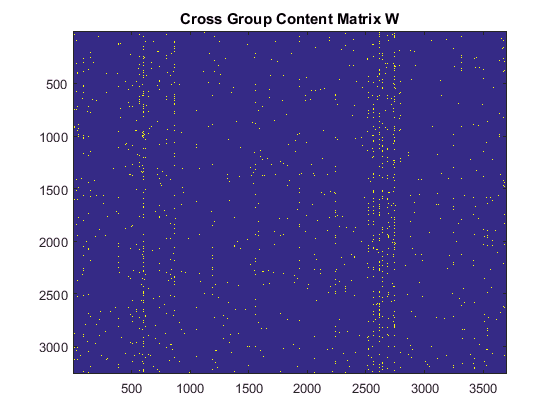

figure
imagesc(W);
title('Cross Group Content Matrix W');

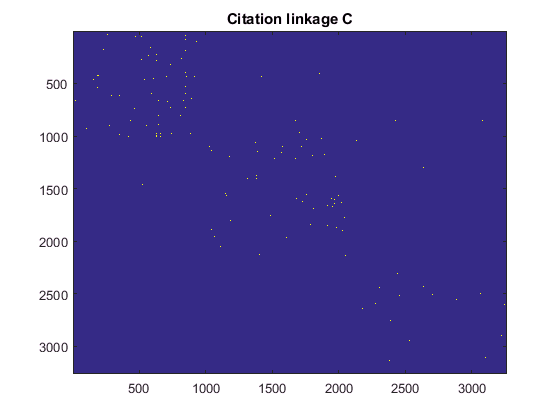


figure
C = C | C.';
imagesc(C);
title('Citation linkage C');

Using linear Transformation and Laplcian for dimensionality reduction

% %Normalized input data
% W = W - min(W(:));   % W = [k*C, W]; result in a lot of small eigenvalues
% W = W/max(W(:));
% W = bsxfun(@minus, W, mean(W,1));
% 
% d = sum(C,2);
% rd = 1./sqrt(d);
% Lc =  eye(M) - bsxfun(@times,bsxfun(@times,C,rd), rd');
% Lc = W'*Lc*W;
% 
% C_ = ~C;
% d_ = sum(C_,2);
% rd_ = 1./sqrt(d_);
% Lc_ =  eye(M) - bsxfun(@times,bsxfun(@times,C_,rd_), rd_');
% Lc_ = W'*Lc_*W;
% [P, Lambda] = eig(Lc, Lc_);
% [~, I] = sort(diag(Lambda), 'ascend');
% X = W*P;
% figure
% Plotcluster(X(:, [I(2),I(3)])', lx);
% title('Linear Laplacian embedding using C and W');

Revision No. 1

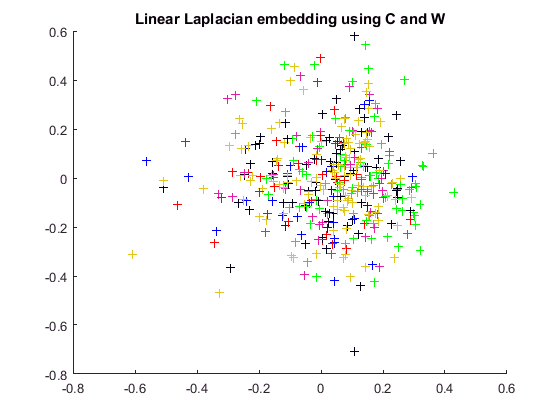

%Preprocessing input data using PCA
W = W - min(W(:));   % W = [k*C, W]; result in a lot of small eigenvalues
W = W/max(W(:));
W = bsxfun(@minus, W, mean(W,1));

% determining the rank of matrix W
r = rank(W, 1e-8);

[U1, lambda] = eig(W'*W);
[lambda, ind] = sort(diag(lambda), 'descend');
U1 = U1(:,ind(1:r));
W = bsxfun(@minus, W, mean(W, 1)) * U1;

C = C - diag(diag(C));
d = sum(C,2);
Lc =  diag(d) - C;
Lc = W'*Lc*W;
Lc = (Lc + Lc.')/2;

C2 = logical(C^3);
C_ = full(~C2);
C_ = C_ - diag(diag(C_));
d_ = sum(C_,2);
Lc_ =  diag(d_) - C_;
Lc_ = W'*Lc_*W;
Lc_ = (Lc_ + Lc_')/2;
[P, Lambda] = eig(Lc_, Lc);
[~, I] = sort(diag(Lambda), 'descend');
X = W*P;
figure
Plotcluster(X(:, [I(1),I(2)])', lx);
title('Linear Laplacian embedding using C and W');

% d = sum(T,2);        % T = [C, lambda*D];
% rd = 1./sqrt(d);
% Lc =  eye(size(T,1)) - bsxfun(@times,bsxfun(@times,T,rd), rd');
% [P, Lambda] = eig(Lc);
% [~, I] = sort(diag(Lambda), 'ascend');
% figure
% Plotcluster(P(:, [I(2),I(1)])', lx);
% title('Linear Laplacian embedding using C and W');

Visualize the embedding using tsne

cut_X = normc(X(:, I(1:50)));

% Compute pairwise distance matrix
sum_X = sum(cut_X .^ 2, 2);
D = bsxfun(@plus, sum_X, bsxfun(@plus, sum_X', -2 * (cut_X * cut_X')));

% Compute joint probabilities
P = d2p(D, 0.01, 1e-5);   

Computed P-values 500 of 3264 datapoints...
Computed P-values 1000 of 3264 datapoints...
Computed P-values 1500 of 3264 datapoints...
Computed P-values 2000 of 3264 datapoints...
Computed P-values 2500 of 3264 datapoints...
Computed P-values 3000 of 3264 datapoints...
Mean value of sigma: 2.9802e-08
Minimum value of sigma: 2.9802e-08
Maximum value of sigma: 2.9802e-08


Iteration 10: error is 51.4041
Iteration 20: error is 49.5593
Iteration 30: error is 48.6913
Iteration 40: error is 48.4684
Iteration 50: error is 48.3755
Iteration 60: error is 48.3215
Iteration 70: error is 48.2811
Iteration 80: error is 48.2517
Iteration 90: error is 48.2294
Iteration 100: error is 2.0636
Iteration 110: error is 1.9737
Iteration 120: error is 1.8935
Iteration 130: error is 1.8506
Iteration 140: error is 1.8223
Iteration 150: error is 1.797
Iteration 160: error is 1.7744
Iteration 170: error is 1.7534
Iteration 180: error is 1.7337
Iteration 190: error is 1.7154
Iteration 200: error is 1.6981
Iteration 210: error is 1.6815
Iteration 220: error is 1.6657
Iteration 230: error is 1.6505
Iteration 240: error is 1.6361
Iteration 250: error is 1.622
Iteration 260: error is 1.5972
Iteration 270: error is 1.5656
Iteration 280: error is 1.5368
Iteration 290: error is 1.5108
Iteration 300: error is 1.4859
Iteration 310: error is 1.4624
Iteration 320: error is 1.4406
Iteration 

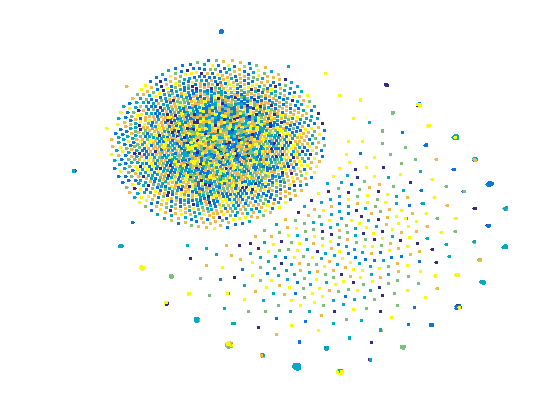

X_2d = tsne_p(P, lx, 2);

save the result

save('citeseer_algo3.mat');